# DIMENSIONALITY REDUCTION - Principal Component Analysis

## DATA DOWNLOAD and LOADING

#### Begin by obtaining the some images from 

#### [**https://generated.photos/faces**](https://generated.photos/faces)

#### **and store them in a folder names "imagesPCA".**

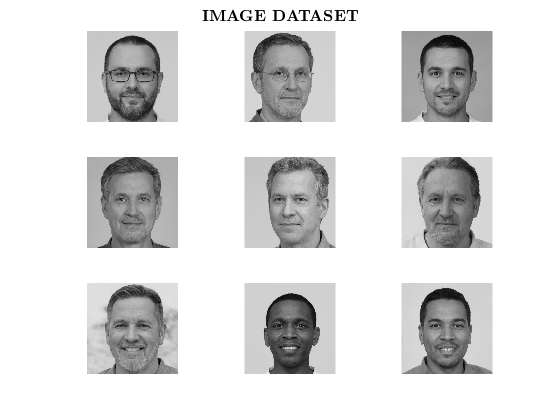

clc; clear; close all

% Store images info in a image datastore, images are searched in the
% directory "imagesPCA" located in the directory when this livescript is
% located (MATLAB path)
imds = imageDatastore(strcat(pwd,"/imagesPCA")) ;
N = size(imds.Files,1); % files in the image datastore
% Organize the data matrix for PCA and display part of the dataset, e.g. 9
% images
figure
img = rgb2gray(readimage(imds,1));  % conversion to gray scale image
subplot(3,3,1)
imshow(img)
imgSize = size(img);

X = zeros(N,imgSize(1)*imgSize(2)); % preallocation of data matrix X
X2 = X;                             % preallocation of the normalized data matrix X2
xi = reshape(img,1,[]);             % flattening of the image array (-> 1D vector)
X(1,:) = xi;
X2(1,:) = normalize(X(1,:));        % data normalization -> auxiliary function at the end

for i = 2:N
    img = rgb2gray(readimage(imds,i));
    if i <= 9
         subplot(3,3,i)
         imshow(img)
    end
    
    xi = reshape(img,1,[]);
    X(i,:) = xi;
    X2(i,:) = normalize(X(i,:));
end
sgtitle('\textbf{IMAGE DATASET}','FontSize',16,'Interpreter','latex')

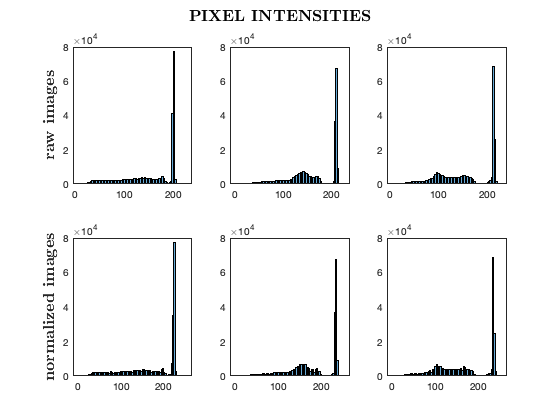

% Comparison of the pixel values for the normal images and the normalized
% ones
figure
subplot(231)
histogram(X(1,:))
ylabel('\textbf{raw images}','Interpreter','latex','FontSize',16)
subplot(232)
histogram(X(2,:))
subplot(233)
histogram(X(6,:))
subplot(234)
histogram(X2(1,:))
ylabel('\textbf{normalized images}','Interpreter','latex','FontSize',16)
subplot(235)
histogram(X2(2,:))
subplot(236)
histogram(X2(6,:))
sgtitle('\textbf{PIXEL INTENSITIES}','FontSize',16,'Interpreter','latex')
% compute the mean of the dataset along the columns (features, pixels)
meanX = mean(X2,1);
% compute the principal components (by default the algorithm remove the mean from the data)
[pcs,scrs,~,~,expl] = pca(X2-meanX);

% Pareto plot to visualize the explained variance of the principal
% scores (eigenvalues)
figure
pareto(expl)

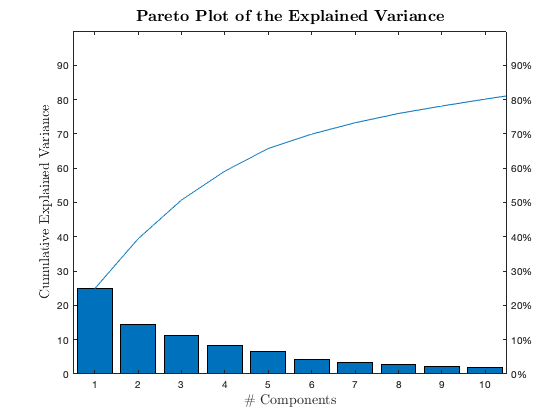

title('\textbf{Pareto Plot of the Explained Variance}','FontSize',16,'Interpreter','latex')
ylabel('Cumulative Explained Variance','Interpreter','latex','FontSize',14)
xlabel('\# Components','Interpreter','latex','FontSize',14)

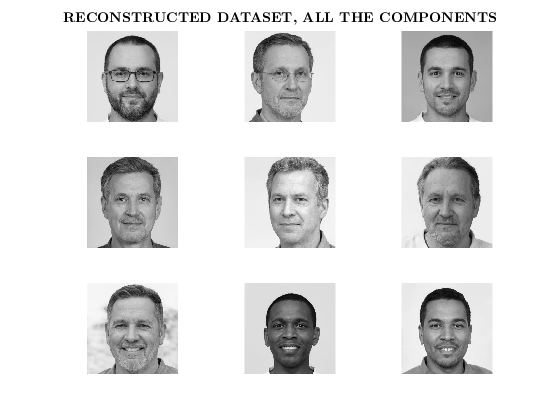

% DATA reconstruction as the linear combination of scores (eigenvalues) and
% principal components (eigenvectors). 
% Don't forget the mean of the data.
Xrec = meanX + scrs*pcs'; % Xrec is a matrix of double numbers

for i = 1:9
    img = uint8(reshape(normalize(Xrec(i,:)),imgSize(1),imgSize(2))); % cast to integer (8 bits)
    subplot(3,3,i)
    imshow(img)
end
sgtitle('\textbf{RECONSTRUCTED DATASET, ALL THE COMPONENTS}','FontSize',14,'Interpreter','latex')

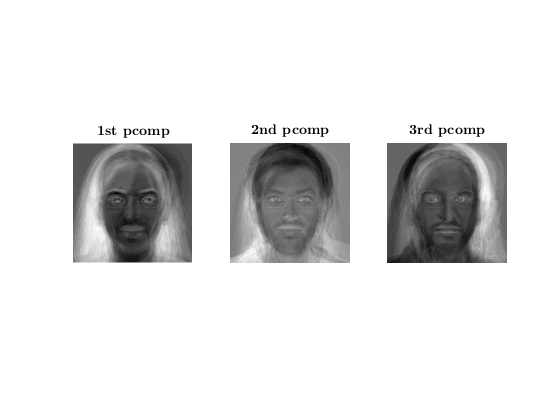

figure
subplot(131)
img = normalize(scrs(1,1)*pcs(:,1)');
imshow(uint8(reshape(img,imgSize(1),imgSize(2))))
title('\textbf{1st pcomp}','FontSize',14,'Interpreter','latex')
subplot(132)
img = normalize(scrs(1,2)*pcs(:,2)');
imshow(uint8(reshape(img,imgSize(1),imgSize(2))))
title('\textbf{2nd pcomp}','FontSize',14,'Interpreter','latex')
subplot(133)
img = normalize(scrs(1,3)*pcs(:,3)');
imshow(uint8(reshape(img,imgSize(1),imgSize(2))))
title('\textbf{3rd pcomp}','FontSize',14,'Interpreter','latex')

sgtitle('\textbf{EIGENFACES}','FontSize',16,'Interpreter','latex')

figure
hold on
x = scrs(:,1);
y = scrs(:,2);
scatter(x,y,25,'filled')
for i = 1:N
    img = uint8(reshape(normalize(Xrec(i,:)),imgSize(1),imgSize(2)));
    xImage = x(i) + [-0.25 0.25]*1e4;   % The x data for the image corners
    yImage = y(i) + [0.25 -0.25]*1e4;   % The y data for the image corners
    image(xImage,yImage,img);
    colormap gray
end
title('\textbf{Dataset Visualization through PCA}','FontSize',14,'Interpreter','latex')
ylabel('\textbf{Second Principal Component}','FontSize',14,'Interpreter','latex')
xlabel('\textbf{First Principal Component}','FontSize',14,'Interpreter','latex')

% Auxiliary function for image data normalization. This function in
% necessary for data visualization when the pixels intensity are not spread
% over the whole values of the colormap 0-255. The effect of normalization
% is to enhance the constrast of the image!

function y = normalize(x)

y = (x-min(x))/(max(x)-min(x))*255;

end